# Face versus Object in Broad and Narrow Spiking Neurons in ACC and BLA

## Loading and curating data

First we can load the neural data, the behavioral events file, and the celltype labels on to the workspace.

clc;
clear;
data_p = fullfile( eisg.util.project_path, 'processed_data');
sorted = shared_utils.io.fload( fullfile(data_p,...
  'sorted_neural_data_social_gaze.mat') );
events = shared_utils.io.fload( fullfile(data_p, 'events.mat') );
ct_labels = load_cell_type_labels( data_p );

Now we can extract the spike-time information with corresponding labels from the `sorted` variable

[unit_spike_ts, unit_wfs, spike_labels] = linearize_sorted( sorted );

And then add information about the subject monkeys on to the `spike_labels` variable

bfw.add_monk_labels( spike_labels );

Now we select the `valid` and `maybe-valid` units, and then assign `cell-type` labels to the corresponding rows in the `spike-labels` variable

[uuid_I, uuids] = findall( spike_labels, 'uuid',...
  find(spike_labels, {'valid-unit', 'maybe-valid-unit'}) );
match_I = bfw.find_combinations( ct_labels, uuids );
for i = 1:numel(uuid_I)
  if ( ~isempty(match_I{i}) )
    ct_label = cellstr( ct_labels, 'cell-type', match_I{i} );
    addsetcat( spike_labels, 'cell-type', ct_label, uuid_I{i} );
  end
end

`ct_labels` contains three types of labels: `n`, `m`, and `b` corresponding to 'narrow', 'medium', and 'broad'. But in reality, the `b` category effectively labels outliers and `m` category actually corresponds to broad spiking units. So we raplace the labels in `spike_labels` accordingly

replace( spike_labels, 'n', 'narrow');
replace( spike_labels, 'm', 'broad');
replace( spike_labels, 'b', 'outlier');

We can then append to the behavioral data, time points corresponding to fixations on `whole_face` and `right_nonsocial_object_whole_face_matched`, and then extract the start times of those fixation events

events = add_whole_face_whole_object_rois( events );
evts = bfw.event_column( events, 'start_time' );

## Extracting PSTH around fixation start times

With the data now formatted to our convenience, we can start with analyzing the neural data. The first step is to extract the spike counts in `10ms` bins from `-0.5s` to `0.5s` around the fixation start times corresponding to looks into the ROIs of interest

rois = { 'whole_face', 'right_nonsocial_object_whole_face_matched',...
  'eyes_nf', 'face' };
evt_mask = find( events.labels, [{'m1'}, rois] );
spk_mask = find( spike_labels, {'valid-unit', 'maybe-valid-unit'} );
min_t = -0.5;
max_t = 0.5;
bin_width = 0.01;
[psth_matrix, psth_labels, t] = compute_psth(...
    unit_spike_ts, spike_labels, spk_mask ...
  , evts, events.labels, evt_mask ...
  , min_t, max_t, bin_width );

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 6).


We then smoothen the `psth_matrix`, because the spiking is very sparse

psth_matrix = smoothdata( psth_matrix, 2, 'movmean', 10 );

## Bin-by-bin ranksum comparison of face vs obj (social-nonsocial) and eyes vs non-eye face (features) activity for each unit

Now for each unit, we compare the spike count across trials in each bin for looks into the ROIs of interest

num_bins = size( psth_matrix, 2 );
ps_social_nonsocial = nan( numel( uuids ), num_bins );
ps_features = nan( numel( uuids ), num_bins );
parfor i=1:num_bins
  rs_outs_social_nonsocial{i} = dsp3.ranksum(psth_matrix(:, i), psth_labels,...
    {'uuid'}, 'whole_face', 'right_nonsocial_object_whole_face_matched' );
  rs_outs_feature{i} = dsp3.ranksum( psth_matrix(:, i), psth_labels,...
    {'uuid'}, 'eyes_nf', 'face' );
  ps_social_nonsocial(:,i) = cellfun(...
    @(x) x.p, rs_outs_social_nonsocial{i}.rs_tables );
  ps_features(:,i) = cellfun( @(x) x.p, rs_outs_feature{i}.rs_tables );
  % fprintf( 'compared bin %d of %d\n', i, num_bins );
end

### Visualizing results

Having calculated the p-values for the ranksum tests, we can now generate a matrix (`units x bins`) and then where each element indicates whether the bin shows a significant activity difference between the ROIs compared. First we define the thresholds and colors corresponding to significant bins for different ROI comparisons

p_thresh = 0.05;
seq_dur_thresh = 5;
sig_social_color = [1, 0, 0]; % red
sig_eye_color = [0, 1, 0]; % green
both_color = [0, 0, 1]; % blue

Now, we generate the corresponding matrices for identifying significant bins

sig_social = ps_social_nonsocial < p_thresh;
sig_eye = ps_features < p_thresh;
sig_both =  sig_eye & sig_social;

For visualization purposes, an image array is generted with the same size as the significance matrices, but with a 3rd dimension for including RGB color values

image_array = ones( size(ps_social_nonsocial, 1),...
  size(ps_social_nonsocial, 2), 3 );

#### Face versus Object Ranksum

We use the `assign_at` function, defined at the end of the script, to assign colors to particular bins of the image array. Using the function, we can get the significant bins corresponding to the face versus object comparison

image_social_nonsocial = assign_at(image_array, sig_social , sig_social_color );

Now we use a filter to exclude `outlier` units and also units from `dmpfc` and `ofc` to reduce crowding and make the visualization better

unit_mask = findnone( rs_outs_social_nonsocial{1}.rs_labels,...
  {'outlier', 'ofc', 'dmpfc'} );

Now we can extract the indices for a particular `cell-type` of a particular `region`

[I, C] = findall( rs_outs_social_nonsocial{1}.rs_labels,...
  {'cell-type', 'region'}, unit_mask );

And then we can generate plots of significant activity difference for each bin for each unit, sorted by the total number of significant face versus object bins

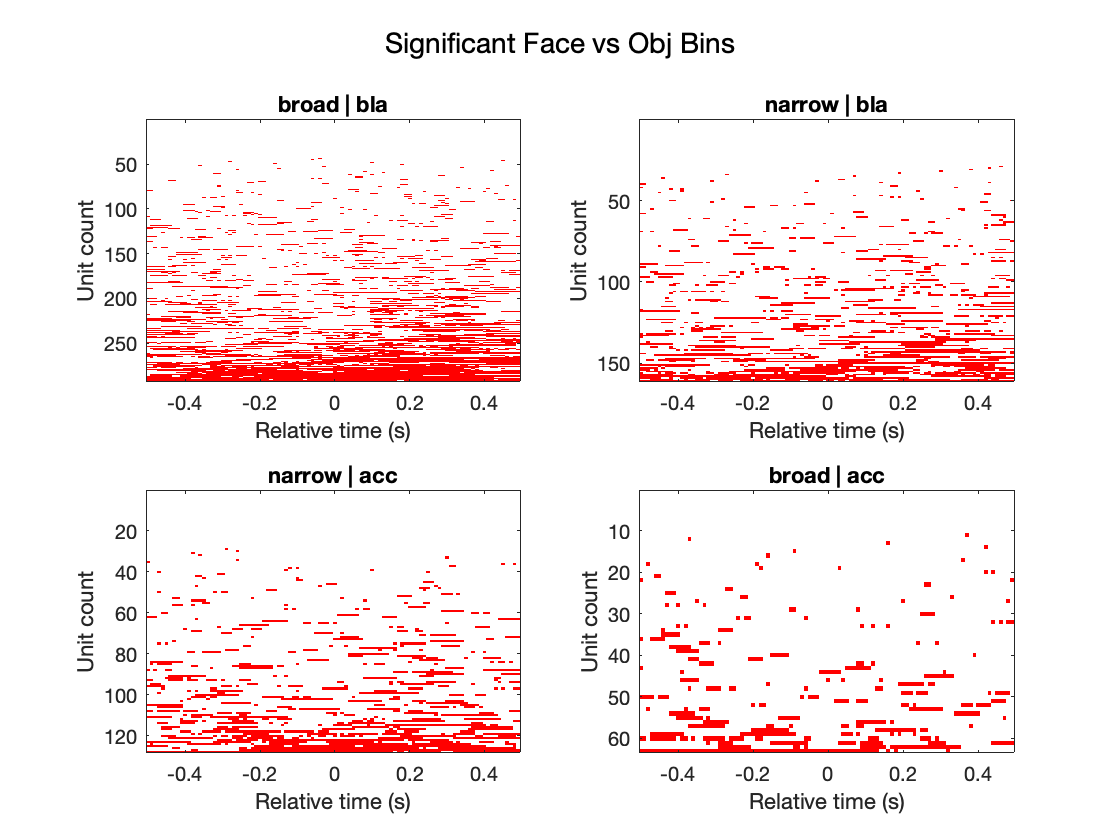

figure();
axs = plots.panels( numel(I) );
for i = 1:numel(axs)
  ind = I{i}; % Count of ind is the number of cells of that type in that region
  tot_sig_eye_bins = sum(sig_social(ind,:),2);
  [~,sorted_ind] = sort(tot_sig_eye_bins);
  image_array_sorted = image_social_nonsocial(ind(sorted_ind), :, :);
  cluster_mat{i} = linkage( double(sig_social(ind,:)), 'ward' );
  % dendrogram( cluster_mat{i}, 'ColorThreshold', max(cluster_mat{i}(:,3))/2 );
  % dendrogram( cluster_mat{i}, numel(ind), 'ColorThreshold', 'default', 'Orientation', 'left' );
  imagesc( axs(i), t, 1:numel(ind), image_array_sorted );
  title( axs(i), strrep(fcat.strjoin(C(:, i), ' | '), '_', ' ') );
  xlabel( axs(i), 'Relative time (s)' );
  ylabel( axs(i), 'Unit count');
end
suptitle('Significant Face vs Obj Bins');

The same plot can be generated, but not only selecting neurons that have at least 5 consecutive significant bins

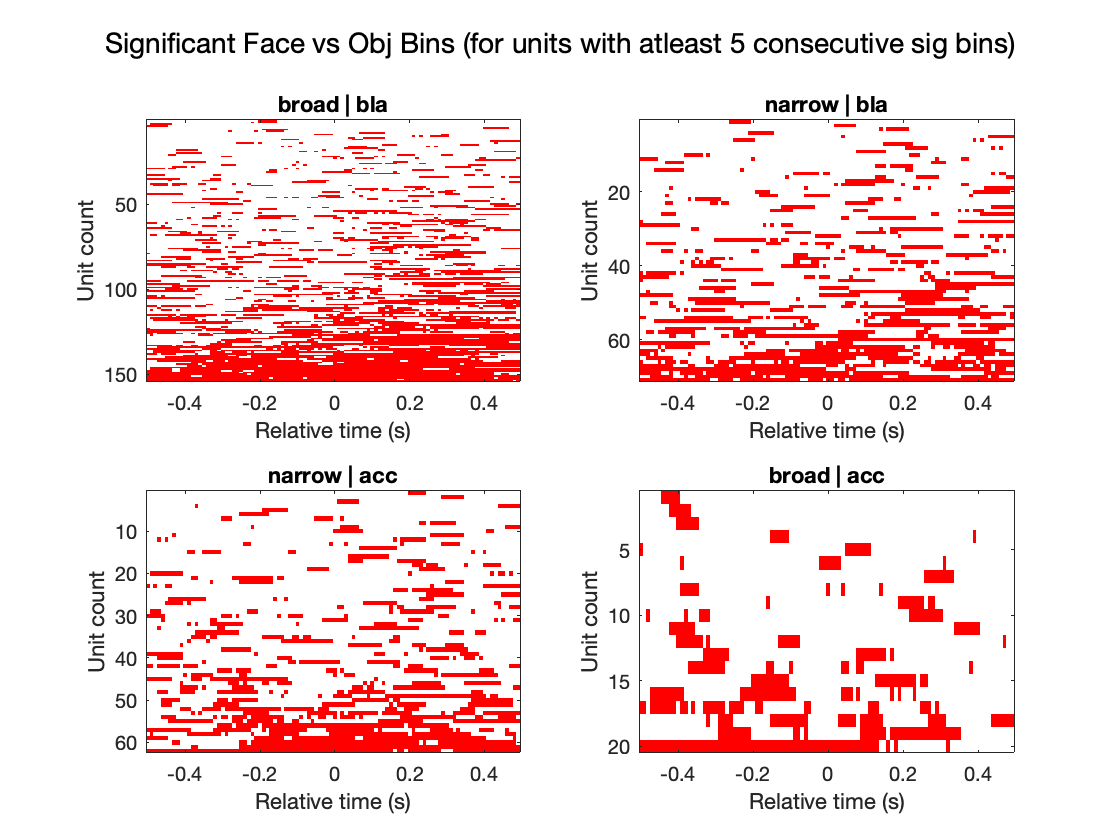

figure();
axs = plots.panels( numel(I) );
for i = 1:numel(axs)
  ind = I{i}; % Count of ind is the number of cells of that type in that region
  ind2 = [];
  for j = ind'
    [~, seq_durs] = shared_utils.logical.find_islands( sig_social(j,:) );
    if max(seq_durs)>=seq_dur_thresh
      ind2 = [ind2; j];
    end
  end
  ind = ind2;
  tot_sig_eye_bins = sum(sig_social(ind,:),2);
  [~,sorted_ind] = sort(tot_sig_eye_bins);
  image_array_sorted = image_social_nonsocial(ind(sorted_ind), :, :);
  imagesc( axs(i), t, 1:numel(ind), image_array_sorted );
  title( axs(i), strrep(fcat.strjoin(C(:, i), ' | '), '_', ' ') );
  xlabel( axs(i), 'Relative time (s)' );
  ylabel( axs(i), 'Unit count');
end
suptitle('Significant Face vs Obj Bins (for units with atleast 5 consecutive sig bins)');

#### Pre and post fixation activity comparison for face and object

From the plots it seems apparent that there might be some difference in the number of bins that are significant post `t=0` and pre `t=0`. We test that out by counting the number of neurons that shows significance for each time bin, and compare the counts for `t<=0` and `t>0`

% Have to make sure that the left and right y axes overlap
figure();
axs = plots.panels( numel(I) );
for i = 1:numel(axs)
  ind = I{i};
  n_units = numel(ind);
  hold on;
  yyaxis( axs(i), "left" );
  count_vec = sum(sig_social(ind,:));
  plot( axs(i), t, count_vec );
  ylim( axs(i), [min(count_vec)*0.9 max(count_vec)*1.1] );
  ylabel( axs(i), 'Number of units');
  yyaxis( axs(i), "right" );
  prop_vec = count_vec/n_units;
  plot( axs(i), t, prop_vec );
  ylim( axs(i), [min(prop_vec)*0.9 max(prop_vec)*1.1] );
  ylabel( axs(i), 'Proportion of units');
  hold off;
  title( axs(i), strrep(fcat.strjoin(C(:, i), ' | '), '_', ' ') );
  xlabel( axs(i), 'Relative time (s)' );  
  t_pre = t>-0.5 & t<=0;
  t_post = t>0 & t<=0.5;
  tot_cells_per_bin_pre = sum(sig_social(ind,t_pre));
  tot_cells_per_bin_post = sum(sig_social(ind,t_post));
  median_pre_cells = median(tot_cells_per_bin_pre);
  median_post_cells = median(tot_cells_per_bin_post);
  ranksum_p = ranksum(tot_cells_per_bin_pre, tot_cells_per_bin_post);
  celltype_and_region = char(fcat.strjoin(C(:, i), ' | '));
  fprintf('%s | median #cells/bin pre: %0.1f; post: %0.1f; ranksum p: %0.3f;\n',...
    celltype_and_region, median_pre_cells, median_post_cells, ranksum_p);
end

broad | bla | median #cells/bin pre: 49.0; post: 65.0; ranksum p: 0.000;


narrow | bla | median #cells/bin pre: 20.0; post: 26.0; ranksum p: 0.000;


narrow | acc | median #cells/bin pre: 16.0; post: 19.0; ranksum p: 0.000;


broad | acc | median #cells/bin pre: 6.0; post: 4.0; ranksum p: 0.002;


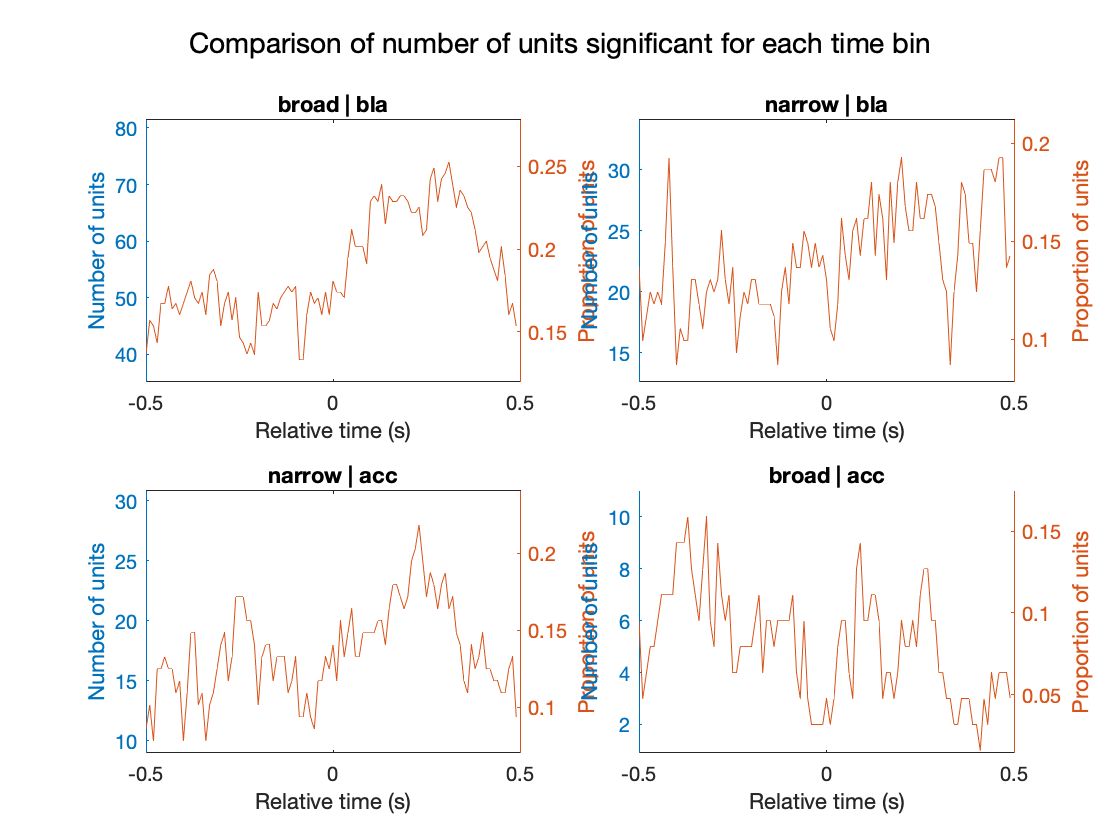

suptitle('Comparison of number of units significant for each time bin');

We expected the difference to be significant for `broad` units in BLA and `narrow` units in ACC, but as it turns out, all the comparisons produce a significant result. The results remain similar even if we just consider the units with at least 5 consecutive significant bins

figure();
axs = plots.panels( numel(I) );
for i = 1:numel(axs)
  ind = I{i}; % Count of ind is the number of cells of that type in that region
  ind2 = [];
  for j = ind'
    [~, seq_durs] = shared_utils.logical.find_islands( sig_social(j,:) );
    if max(seq_durs)>=seq_dur_thresh
      ind2 = [ind2; j];
    end
  end
  ind = ind2;
  tot_sig_social_bins = sum(sig_social(ind,:),2);
  [~,sorted_ind] = sort(tot_sig_social_bins);
  image_array_sorted = image_social_nonsocial(ind(sorted_ind), :, :);
  plot( axs(i), t, sum(sig_social(ind,:)) );
  title( axs(i), strrep(fcat.strjoin(C(:, i), ' | '), '_', ' ') );
  xlabel( axs(i), 'Relative time (s)' );
  ylabel( axs(i), 'Number of units');
  t_pre = t>-0.5 & t<=0;
  t_post = t>0 & t<=0.5;
  tot_cells_per_bin_pre = sum(sig_social(ind,t_pre));
  tot_cells_per_bin_post = sum(sig_social(ind,t_post));
  median_pre_cells = median(tot_cells_per_bin_pre);
  median_post_cells = median(tot_cells_per_bin_post);
  ranksum_p = ranksum(tot_cells_per_bin_pre, tot_cells_per_bin_post);
  celltype_and_region = char(fcat.strjoin(C(:, i), ' | '));
  fprintf('%s | median #cells/bin pre: %0.1f; post: %0.1f; ranksum p: %0.3f;\n',...
    celltype_and_region, median_pre_cells, median_post_cells, ranksum_p);
end

broad | bla | median #cells/bin pre: 44.0; post: 60.0; ranksum p: 0.000;


narrow | bla | median #cells/bin pre: 17.0; post: 22.0; ranksum p: 0.000;


narrow | acc | median #cells/bin pre: 14.0; post: 18.0; ranksum p: 0.000;


broad | acc | median #cells/bin pre: 4.0; post: 3.0; ranksum p: 0.005;


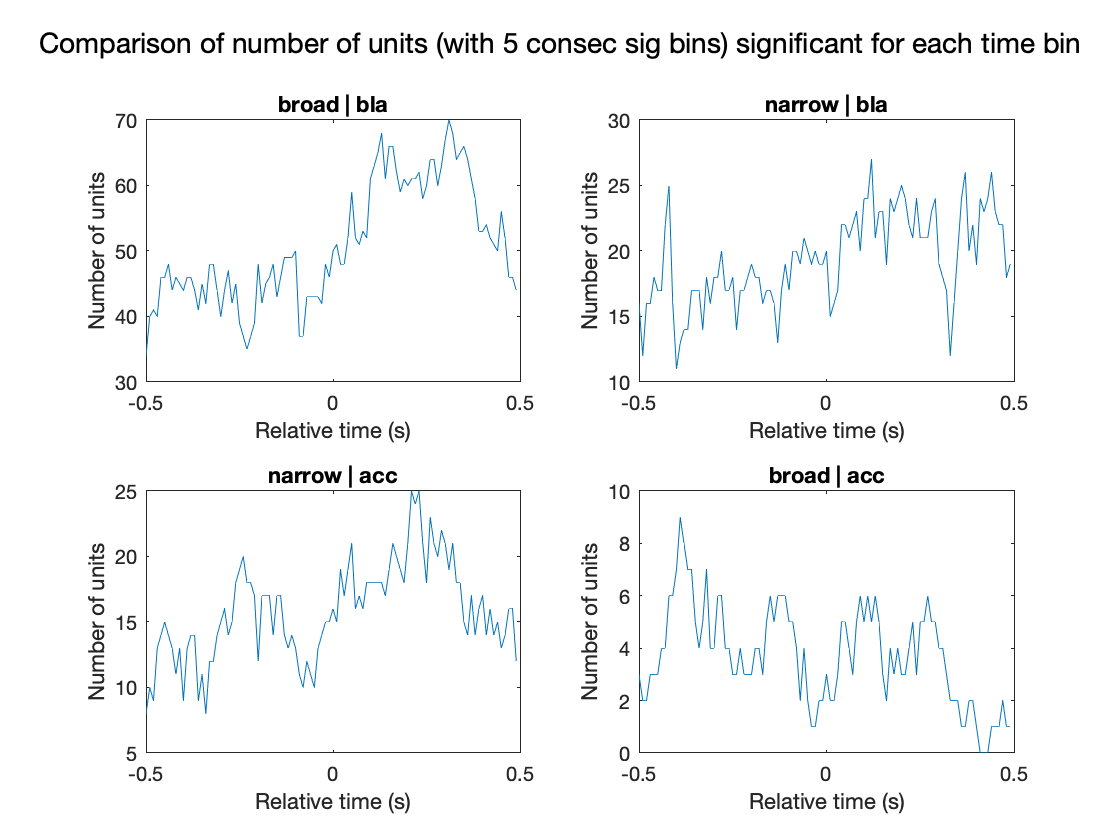

suptitle('Comparison of number of units (with 5 consec sig bins) significant for each time bin');

Another way of comparing the number of units that show significance pre and post fixation is to count the mean number of units that are significant in the `pre` time and that in the `post` time, and then comparing them as a fraction of total number of units of that particular type, using a chi-squared proportion test

for i = 1:numel(I)
  ind = I{i}; % Count of ind is the number of cells of that type in that region
  tot_sig_social_bins = sum(sig_social(ind,:),2);
  [~,sorted_ind] = sort(tot_sig_social_bins);
  t_pre = t>-0.5 & t<=0;
  t_post = t>0 & t<=0.5;
  tot_cells_per_bin_pre = sum(sig_social(ind,t_pre));
  tot_cells_per_bin_post = sum(sig_social(ind,t_post));
  median_pre_cells = median(tot_cells_per_bin_pre);
  median_post_cells = median(tot_cells_per_bin_post);
  [h, proptest_p, chi2stat] = prop_test(...
    [median_pre_cells, median_post_cells], [numel(ind), numel(ind)], false );
  ranksum_p = ranksum(tot_cells_per_bin_pre, tot_cells_per_bin_post);
  celltype_and_region = char(fcat.strjoin(C(:, i), ' | '));
  fprintf('%s | mean fraction of units/bin pre: %d/%d; post: %d/%d; chi2p: %0.3f;\n',...
    celltype_and_region, median_pre_cells, numel(ind), median_post_cells, numel(ind), proptest_p);
end

broad | bla | mean fraction of units/bin pre: 49/293; post: 65/293; chi2p: 0.095;
narrow | bla | mean fraction of units/bin pre: 20/161; post: 26/161; chi2p: 0.339;
narrow | acc | mean fraction of units/bin pre: 16/128; post: 19/128; chi2p: 0.585;
broad | acc | mean fraction of units/bin pre: 6/63; post: 4/63; chi2p: 0.510;


We can try the same analysis again, but only for units that have 5 or more consecutive significant bins

for i = 1:numel(I)
  ind = I{i}; % Count of ind is the number of cells of that type in that region
  ind2 = [];
  for j = ind'
    [~, seq_durs] = shared_utils.logical.find_islands( sig_social(j,:) );
    if max(seq_durs)>=seq_dur_thresh
      ind2 = [ind2; j];
    end
  end
  ind = ind2;
  tot_sig_eye_bins = sum(sig_social(ind,:),2);
  [~,sorted_ind] = sort(tot_sig_eye_bins);
  t_pre = t>-0.5 & t<=0;
  t_post = t>0 & t<=0.5;
  tot_cells_per_bin_pre = sum(sig_social(ind,t_pre));
  tot_cells_per_bin_post = sum(sig_social(ind,t_post));
  median_pre_cells = median(tot_cells_per_bin_pre);
  median_post_cells = median(tot_cells_per_bin_post);
  [h, proptest_p, chi2stat] = prop_test(...
    [median_pre_cells, median_post_cells], [numel(ind), numel(ind)], false );
  ranksum_p = ranksum(tot_cells_per_bin_pre, tot_cells_per_bin_post);
  celltype_and_region = char(fcat.strjoin(C(:, i), ' | '));
  fprintf('%s | mean fraction of units/bin pre: %d/%d; post: %d/%d; chi2p: %0.3f;\n',...
    celltype_and_region, median_pre_cells, numel(ind), median_post_cells, numel(ind), proptest_p);
end

broad | bla | mean fraction of units/bin pre: 44/154; post: 60/154; chi2p: 0.054;
narrow | bla | mean fraction of units/bin pre: 17/71; post: 22/71; chi2p: 0.347;
narrow | acc | mean fraction of units/bin pre: 14/62; post: 18/62; chi2p: 0.412;
broad | acc | mean fraction of units/bin pre: 4/20; post: 3/20; chi2p: 0.677;


As we can observe, other than in the case of BLA, the Chi-squared p-values does not seem to reach significance.

#### Eyes versus Non-eye face Ranksum

First we generate the image matrix corresponding to significant eyes versus non-eye face bins

image_eyes_nef = assign_at( image_array, sig_eye , sig_eye_color );

And then we can plot the matrix

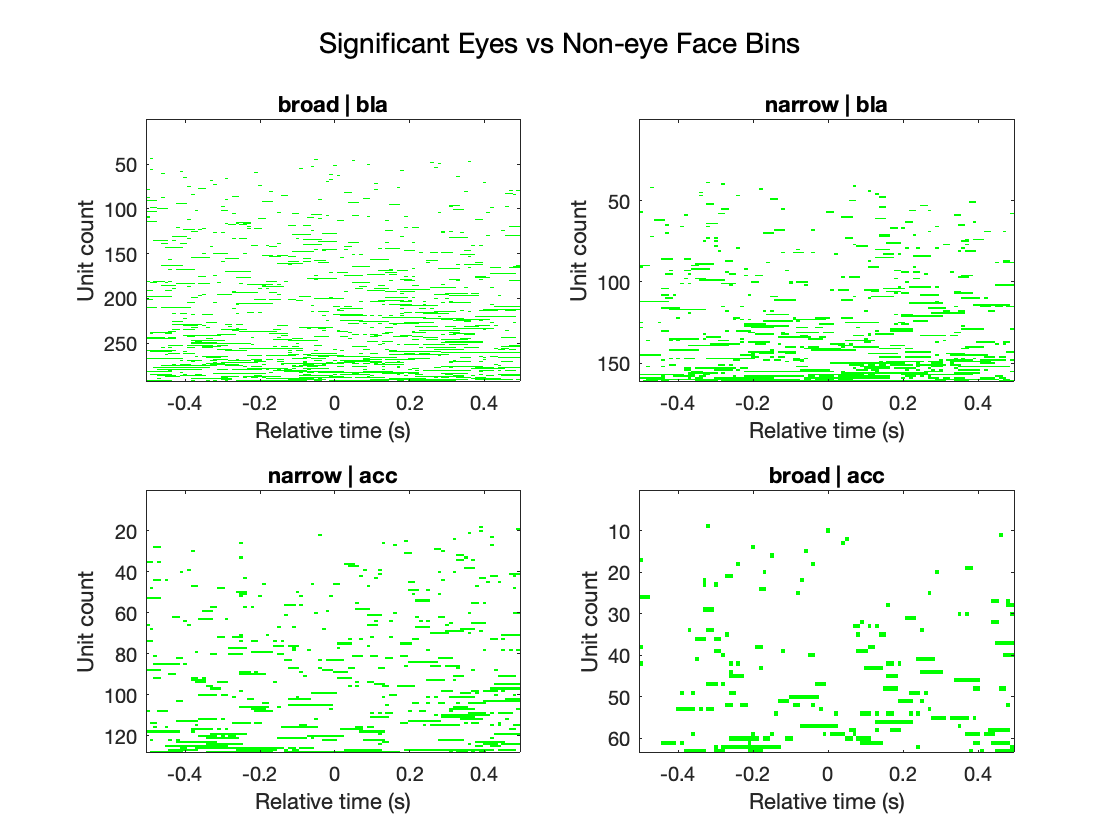

figure();
axs = plots.panels( numel(I) );
for i = 1:numel(axs)
  ind = I{i}; % Count of ind is the number of cells of that type in that region
  tot_sig_eye_bins = sum(sig_eye(ind,:),2);
  [~,sorted_ind] = sort(tot_sig_eye_bins);
  image_array_sorted = image_eyes_nef(ind(sorted_ind), :, :);
  imagesc( axs(i), t, 1:numel(ind), image_array_sorted );
  title( axs(i), strrep(fcat.strjoin(C(:, i), ' | '), '_', ' ') );
  xlabel( axs(i), 'Relative time (s)' );
  ylabel( axs(i), 'Unit count');
end
suptitle('Significant Eyes vs Non-eye Face Bins');

Once again, we can select just the cells that have 5 or more consecutive significant bins

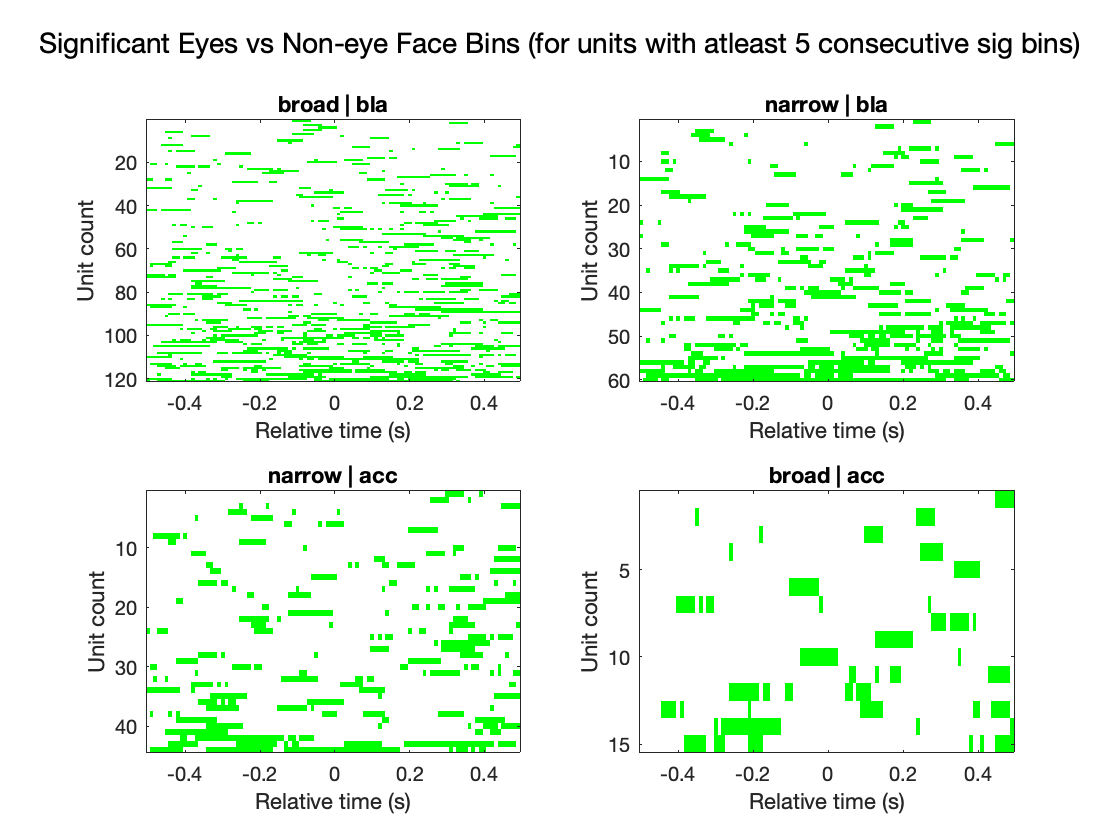

figure();
axs = plots.panels( numel(I) );
for i = 1:numel(axs)
  ind = I{i}; % Count of ind is the number of cells of that type in that region
  ind2 = [];
  for j = ind'
    [~, seq_durs] = shared_utils.logical.find_islands( sig_eye(j,:) );
    if max(seq_durs)>=seq_dur_thresh
      ind2 = [ind2; j];
    end
  end
  ind = ind2;
  tot_sig_eye_bins = sum(sig_eye(ind,:),2);
  [~,sorted_ind] = sort(tot_sig_eye_bins);
  image_array_sorted = image_eyes_nef(ind(sorted_ind), :, :);
  imagesc( axs(i), t, 1:numel(ind), image_array_sorted );
  title( axs(i), strrep(fcat.strjoin(C(:, i), ' | '), '_', ' ') );
  xlabel( axs(i), 'Relative time (s)' );
  ylabel( axs(i), 'Unit count');
end
suptitle('Significant Eyes vs Non-eye Face Bins (for units with atleast 5 consecutive sig bins)');

#### Pre and post fixation activity comparison for eyes and non-eye face

We can check if there is any difference in the number of units that show significant activity pre and post fixation

figure();
axs = plots.panels( numel(I) );
for i = 1:numel(axs)
  ind = I{i}; % Count of ind is the number of cells of that type in that region
  tot_sig_eye_bins = sum(sig_eye(ind,:),2);
  [~,sorted_ind] = sort(tot_sig_eye_bins);
  image_array_sorted = image_social_nonsocial(ind(sorted_ind), :, :);
  plot( axs(i), t, sum(sig_eye(ind,:)) );
  title( axs(i), strrep(fcat.strjoin(C(:, i), ' | '), '_', ' ') );
  xlabel( axs(i), 'Relative time (s)' );
  ylabel( axs(i), 'Number of units');
  t_pre = t>-0.5 & t<=0;
  t_post = t>0 & t<=0.5;
  tot_cells_per_bin_pre = sum(sig_eye(ind,t_pre));
  tot_cells_per_bin_post = sum(sig_eye(ind,t_post));
  median_pre_cells = median(tot_cells_per_bin_pre);
  median_post_cells = median(tot_cells_per_bin_post);
  ranksum_p = ranksum(tot_cells_per_bin_pre, tot_cells_per_bin_post);
  celltype_and_region = char(fcat.strjoin(C(:, i), ' | '));
  fprintf('%s | median #cells/bin pre: %0.1f; post: %0.1f; ranksum p: %0.3f;\n',...
    celltype_and_region, median_pre_cells, median_post_cells, ranksum_p);
end

broad | bla | median #cells/bin pre: 25.0; post: 27.0; ranksum p: 0.106;


narrow | bla | median #cells/bin pre: 14.0; post: 16.0; ranksum p: 0.001;


narrow | acc | median #cells/bin pre: 10.0; post: 11.0; ranksum p: 0.046;


broad | acc | median #cells/bin pre: 3.0; post: 4.0; ranksum p: 0.083;


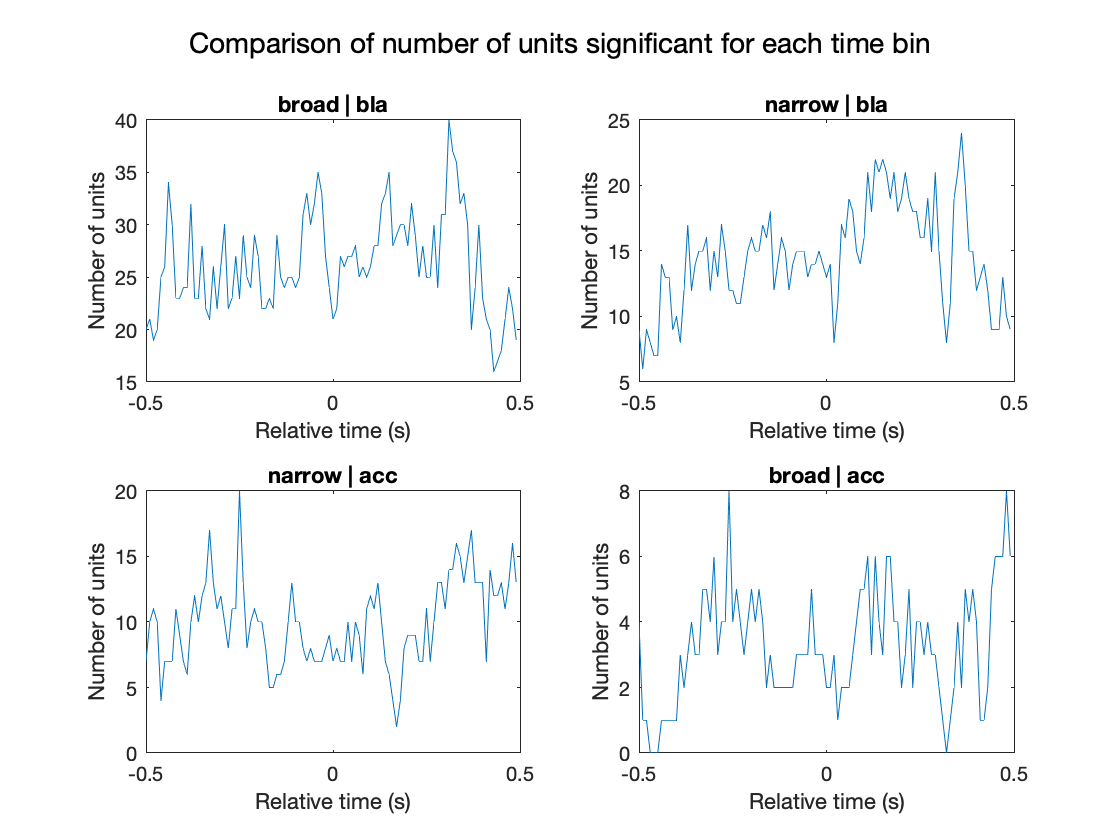

suptitle('Comparison of number of units significant for each time bin');

And if we select just those units that have 5 or more consecutive significant bins

figure();
axs = plots.panels( numel(I) );
for i = 1:numel(axs)
  ind = I{i}; % Count of ind is the number of cells of that type in that region
  ind2 = [];
  for j = ind'
    [~, seq_durs] = shared_utils.logical.find_islands( sig_eye(j,:) );
    if max(seq_durs)>=seq_dur_thresh
      ind2 = [ind2; j];
    end
  end
  ind = ind2;
  tot_sig_eye_bins = sum(sig_eye(ind,:),2);
  [~,sorted_ind] = sort(tot_sig_eye_bins);
  image_array_sorted = image_social_nonsocial(ind(sorted_ind), :, :);
  plot( axs(i), t, sum(sig_eye(ind,:)) );
  title( axs(i), strrep(fcat.strjoin(C(:, i), ' | '), '_', ' ') );
  xlabel( axs(i), 'Relative time (s)' );
  ylabel( axs(i), 'Number of units');
  t_pre = t>-0.5 & t<=0;
  t_post = t>0 & t<=0.5;
  tot_cells_per_bin_pre = sum(sig_eye(ind,t_pre));
  tot_cells_per_bin_post = sum(sig_eye(ind,t_post));
  median_pre_cells = median(tot_cells_per_bin_pre);
  median_post_cells = median(tot_cells_per_bin_post);
  ranksum_p = ranksum(tot_cells_per_bin_pre, tot_cells_per_bin_post);
  celltype_and_region = char(fcat.strjoin(C(:, i), ' | '));
  fprintf('%s | median #cells/bin pre: %0.1f; post: %0.1f; ranksum p: %0.3f;\n',...
    celltype_and_region, median_pre_cells, median_post_cells, ranksum_p);
end

broad | bla | median #cells/bin pre: 19.0; post: 23.0; ranksum p: 0.003;


narrow | bla | median #cells/bin pre: 12.0; post: 14.0; ranksum p: 0.002;


narrow | acc | median #cells/bin pre: 7.0; post: 7.0; ranksum p: 0.869;


broad | acc | median #cells/bin pre: 2.0; post: 2.0; ranksum p: 0.124;


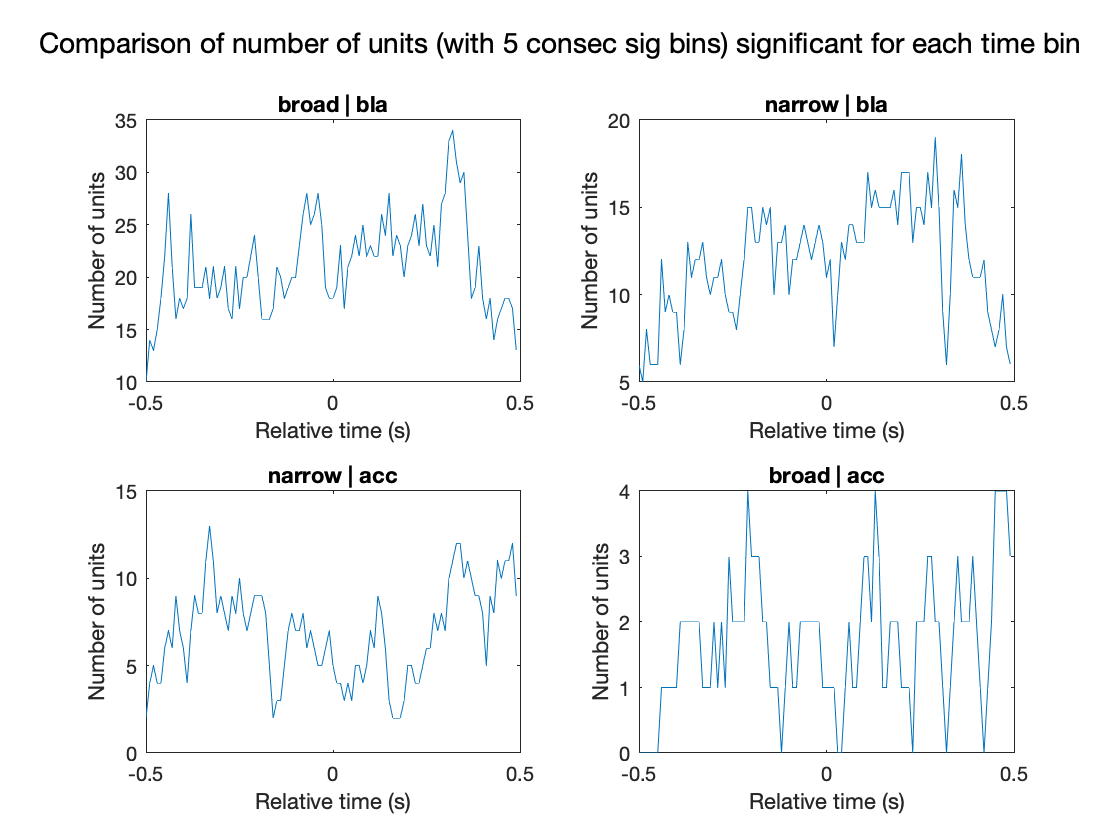

suptitle('Comparison of number of units (with 5 consec sig bins) significant for each time bin');

### ROC analysis: Bin-by-bin AUC evaluation for labeling face and obj fixations using neural spikes

We can try another approach of analysing the information in the neural spikes. Using the ROC method in signal detection theory, we can investigate if the spike counts of a neuron can be used to label if a fixation was made on the face or on a nonsocial object. Here, we assume that the activity corresponding to faces is more than that of an object. Then, for each time bin, we can then calculate the probability that the activity corresponding to faces is more than that of objects -- this is the AUC value. A value of `0.5`, thus, corresponds to the case where neither of the ROIs show differential activity. `AUC>0.5` indicates that our initial assumption that activity of face is greater than objects is correct, with the probability of the AUC value. `AUC<0.5` is similarly informative, but indicates that the ranks must be flipped, i.e. activity of objects is greater than that of faces. To inspect if the AUC values are significant, we can generate a null distribution of AUCs to compare them with, where the labels corresponding to the spike-counts (face or object) has been shuffled

[auc_labels, unit_I] = keepeach( psth_labels', 'uuid' );
roi_a = 'whole_face';
roi_b = 'right_nonsocial_object_whole_face_matched';
aucs = nan( numel(unit_I), size(psth_matrix, 2) );
null_aucs = cell( numel(unit_I), 1 );
perm_p = nan( size(aucs) );
z_scored_aucs = nan( size(aucs) );
parfor i = 1:numel(unit_I)
  % fprintf( '%d of %d\n', i, numel(unit_I) );
  ind_a = find( psth_labels, roi_a, unit_I{i} );
  ind_b = find( psth_labels, roi_b, unit_I{i} );
  aucs(i, :) = auc_over_time( psth_matrix, ind_a, ind_b ); 
  null_aucs{i} = auc_perm_test( psth_matrix, ind_a, ind_b, 100 );
  z_scored_aucs(i, :) = (aucs(i, :) - mean( null_aucs{i}, 1 )) ./ std( null_aucs{i}, [], 1 );  
end

First we remove the units from `ofc` and `dmpfc` and also the `outlier` `cell-type` category, and then separate the units by `cell-type` and `region`

unit_mask = findnone( auc_labels, {'outlier', 'ofc', 'dmpfc'} );
[I, C] = findall( auc_labels, {'cell-type', 'region'}, unit_mask );

Now we can plot out the raw `AUC` values

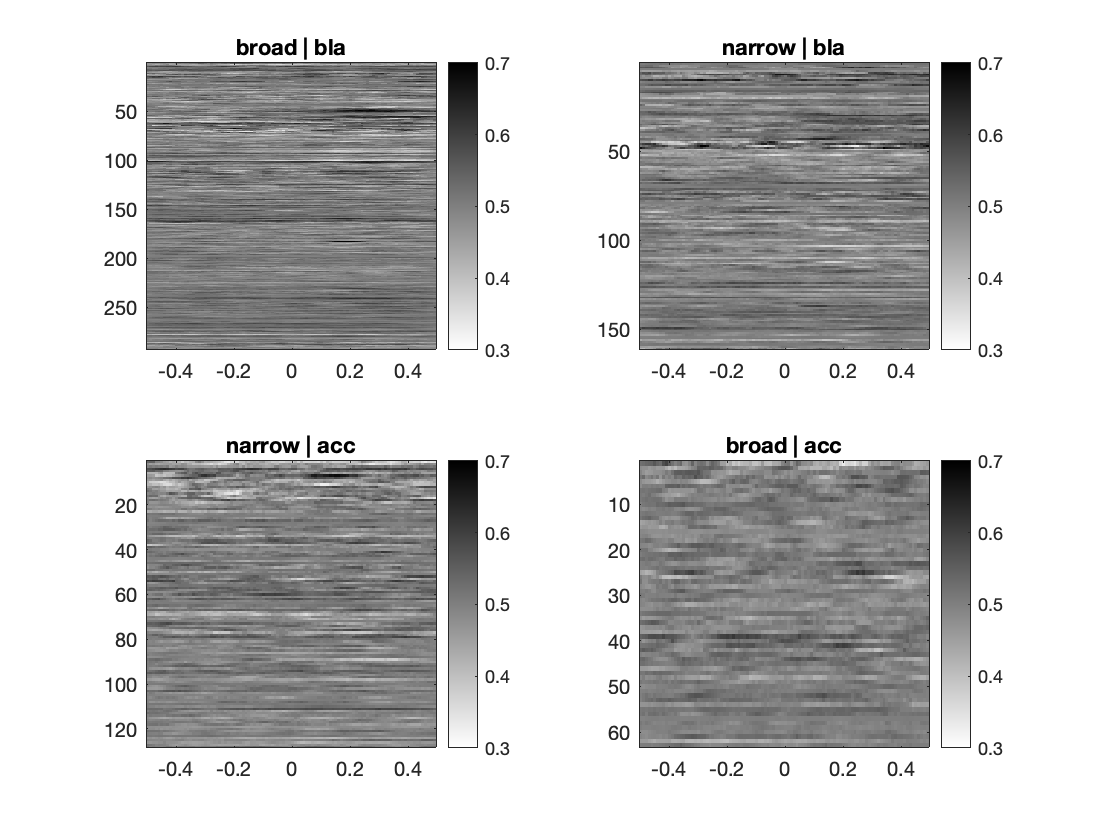

figure();
axs = plots.panels( numel(I) );
for i = 1:numel(axs)
  ind = I{i};
  imagesc( axs(i), t, 1:numel(ind), aucs(ind, :) );
  colorbar( axs(i) );
  cmap = flip( gray );
  blue_map = [zeros(100, 1), zeros(100, 1), linspace(0, 255, 1)']; % Blue
  colormap( axs(i), blue_map );
  set( axs(i), 'clim', [0.3, 0.7] );
  title( axs(i), strrep(fcat.strjoin(C(:, i), ' | '), '_', ' ') );
end

To note is the fact that the farther the `AUC` value is from `0.5`, the better. So, we can sort the units by the location of the bin that has the value farthest from `0.5`

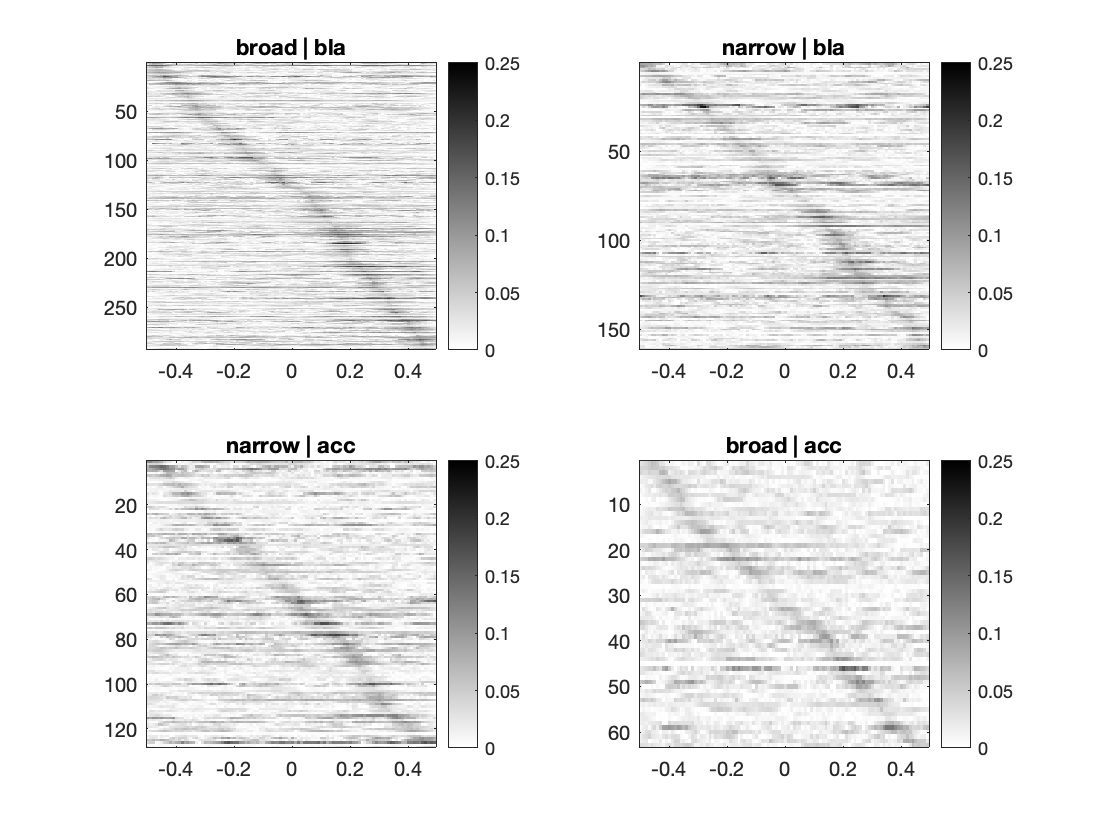

figure();
axs = plots.panels( numel(I) );
for i = 1:numel(axs)
  ind = I{i};
  ind2 = [];
  auc_dev{i} = abs(aucs(ind,:) - 0.5);
  [max_devs{i}, max_dev_loc{i}] = max( auc_dev{i}, [], 2);
  [~,sorted_ind{i}] = sort(max_dev_loc{i});
  %imagesc( axs(i), t, 1:numel(ind), aucs(ind(sorted_ind), :) );
  imagesc( axs(i), t, 1:numel(ind), auc_dev{i}(sorted_ind{i}, :) );
  colorbar( axs(i) );
  %set( axs(i), 'clim', [0.3, 0.65] );
  set( axs(i), 'clim', [0, 0.25] );
  cmap = flip( gray );
  colormap( axs(i), cmap );
  title( axs(i), strrep(fcat.strjoin(C(:, i), ' | '), '_', ' ') );
end

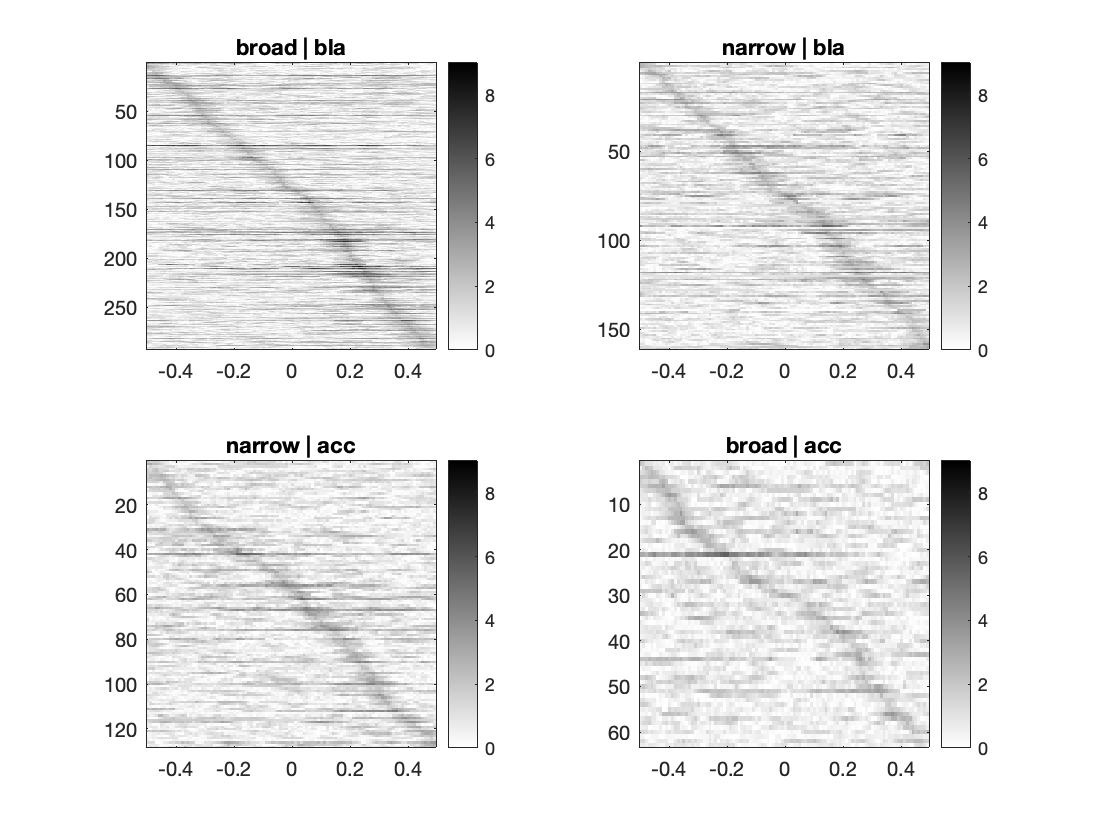

% significant_mask = findor( auc_labels, anova_cell_ids );
unit_mask = findnone( auc_labels, {'outlier', 'ofc', 'dmpfc'} );
[I, C] = findall( auc_labels, {'cell-type', 'region'}, unit_mask );
figure();
axs = plots.panels( numel(I) );
for i = 1:numel(axs)
  ind = I{i};
  %ind = intersect( ind, significant_mask );
  abs_zscore_auc{i} = abs(z_scored_aucs(ind,:));
  [max_aucs{i}, max_auc_loc{i}] = max( abs_zscore_auc{i}, [], 2);
  [~,sorted_ind{i}] = sort(max_auc_loc{i});
  max_auc_times{i} = t(max_auc_loc{i});
  pre_250_ms_inds{i} = max_auc_times{i} > -0.25 & max_auc_times{i} <= 0;
  post_250_ms_inds{i} = max_auc_times{i} > 0 & max_auc_times{i} <= 0.25;
  around_fixation{i} = max_auc_times{i} > -0.2 & max_auc_times{i} <= 0.2;
  imagesc( axs(i), t, 1:numel(ind), abs_zscore_auc{i}(sorted_ind{i}, :) );
  %imagesc( axs(i), t, 1:numel(ind), auc_dev(sorted_ind, :) );
  colorbar( axs(i) );
  set( axs(i), 'clim', [0, 9] );
  cmap = flip( gray );
  % blue_map = [linspace(1, 0, 100)', linspace(1, 0, 100)', linspace(1, 1, 100)']; % Blue
  % colormap( axs(i), blue_map );
  % cmap = 'gray';
  colormap( axs(i), cmap );
  title( axs(i), strrep(fcat.strjoin(C(:, i), ' | '), '_', ' ') );
end


% Find the latency (cell 2) - latency (cell 1) in a ordered list of
% latencies and then compare the delta t distribution
% >> diff(t(max_auc_loc{i}(sorted_ind{i})));

To determine which of the AUC bins show a significant deviation from `0.5`, we z-scored the AUC values with the mean and standard deviation of the corresponding null distribution, obtained from shuffled labels. We know that `1.96` standard deviations on either side captures 95% mass of a normal distribution. That threshold can be used to isolate the bins with a significant AUC value

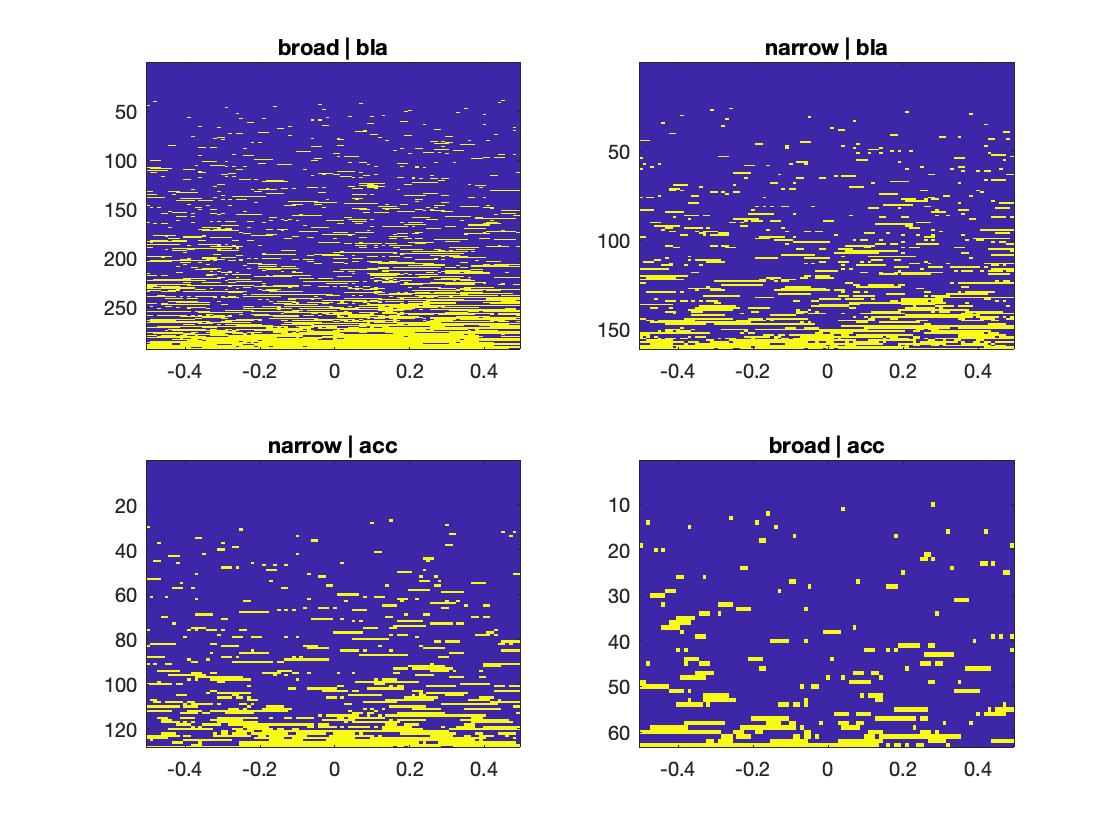

sig_auc_face_obj = abs(z_scored_aucs) > 1.96;
axs = plots.panels( numel(I) );
figure();
for i = 1:numel(axs)
  ind = I{i};
  tot_sig_social_bins = sum(sig_auc_face_obj(ind,:),2);
  [~,sorted_ind] = sort(tot_sig_social_bins);
  imagesc( axs(i), t, 1:numel(ind), sig_auc_face_obj(ind(sorted_ind), :) );
  title( axs(i), strrep(fcat.strjoin(C(:, i), ' | '), '_', ' ') );
end

## Function list

#### Assign At

function im_out = assign_at(im, inds, color)

im_out = im;
[row, col] = find( inds );
for i = 1:numel(row)
  im_out(row(i), col(i), :) = color;
end

end

#### AUC Over Time

function aucs = auc_over_time(spikes, ind_a, ind_b)

aucs = nan( 1, size(spikes, 2) );
for i = 1:size(spikes, 2)
  spks_a = spikes(ind_a, i);
  spks_b = spikes(ind_b, i);
  auc = score_auc( spks_a, spks_b );
  aucs(i) = auc;
end

end

#### AUC Perm Test

function null_aucs = auc_perm_test(spikes, ind_a, ind_b, perm_iters)

null_aucs = cell( perm_iters, 1 );
for i = 1:perm_iters
  [ia, ib] = shuffle2( ind_a, ind_b );
  null_aucs{i} = auc_over_time( spikes, ia, ib );
end
null_aucs = vertcat( null_aucs{:} );
null_aucs = sort( null_aucs );

end

#### 2D Shuffle

function [ic, id] = shuffle2(ia, ib)

i = [ia; ib];
i = i(randperm(numel(i)));
ic = i(1:numel(ia));
id = i(numel(ia)+1:end);
assert( numel(ic) == numel(ia) && numel(id) == numel(ib) );

end

#### AUC Score

function auc = score_auc(a, b)

t = false( numel(a) + numel(b), 1 );
t(1:numel(a)) = true;
y = [ a; b ];
auc = scoreAUC( t, y );

end


#### Fast AUC

Copied over from: https://www.mathworks.com/matlabcentral/fileexchange/50962-fast-auc

function auc = scoreAUC(labels,scores)
% Calculates the AUC - area under the curve.
%
% Besides being the area under the ROC curve, AUC is has a slightly 
% less known interpretation:
% If you choose a random pair of samples which is one positive and one
% negative - AUC is the probabilty that the positive-sample score is above
% the negative-sample score.
% Here we compute the AUC by counting these pairs.
% 
% auc = scoreAUC(labels,scores)
% N x 1 boolean labels
% N x 1 scores
%
% http://www.springerlink.com/content/nn141j42838n7u21/fulltext.pdf
%
% ==== Lior Kirsch 2014 ====

assert( islogical(labels) ,'labels input should be logical');
assert( isequal(size(labels),size(scores)) ,'labels and scores should have the same size');

[n,m] = size(labels);
assert( m==1, 'should have sizse of (n,1)');

num_pos = sum(labels);
num_neg = n - num_pos;
assert( ~(num_pos==0), 'no positive labels entered');
assert( ~(num_pos==n), 'no negative labels entered');


ranks = tiedrank(scores);
auc = ( sum( ranks(labels) ) - num_pos * (num_pos+1)/2) / ( num_pos * num_neg);

end